# Chapter7

clear

## オブザーバ

A = [0 1; -4 -5];
B = [0; 1];
C = [1 0];
D = 0;
P = ss(A, B, C, D)

P =
 
  A = 
       x1  x2
   x1   0   1
   x2  -4  -5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
連続時間状態空間モデル。
モデル プロパティ



A = [0 1; -4 -5];
B = [0; 1];
C = [1 0; 0 1];
D = [0; 0];
Ps = ss(A, B, C, D)

Ps =
 
  A = 
       x1  x2
   x1   0   1
   x2  -4  -5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
連続時間状態空間モデル。
モデル プロパテ

### **オブザーバゲインの設計（極配置）**

% オブザーバ極
observer_poles = [-10+5j,-10-5j];

% オブザーバゲインの設計（状態フィードバックの双対） 
L = -acker(P.A', P.C', observer_poles)'

L =    -15
   -46


eig(P.A + L*P.C)

ans =  -10.0000 + 5.0000i
 -10.0000 - 5.0000i


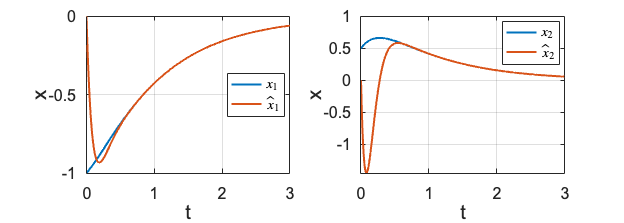

G = ss(P.A, P.B, eye(2), [0 ; 0]);
Obs = ss(P.A + L*P.C, [P.B, -L], eye(2), [0,0; 0,0] );

t = 0:0.01:3;
X0 = [-1, 0.5];
x = initial(G, X0, t);

figure();
subplot(1,2,1);
plot(t, x(:,1), 'linewidth', 2);
hold on;
subplot(1,2,2);
plot(t, x(:,2), 'linewidth', 2);
hold on;

%%%%
% 入力 u = Fx
u = [0 0]*x';
% 出力 y = Cx
y = P.C*x';
% オブザーバで推定した状態の振る舞い
xhat = lsim(Obs, [u ; y], t, [0, 0]);
subplot(1,2,1);
plot(t, xhat(:,1), 'linewidth', 2, 'DisplayName','$\hat{x}_1$');
plot_set(gcf, 't', 'x', 'best')
legend('$x_1$','$\hat{x}_1$', 'Interpreter', 'latex');
subplot(1,2,2);
plot(t, xhat(:,2), 'linewidth', 2, 'DisplayName','$\hat{x}_2$');
plot_set(gcf, 't', 'x', 'best')
legend('$x_2$','$\hat{x}_2$', 'Interpreter', 'latex');

set(gcf,'Position',[100 100 700 250])

### 出力フィードバック

% レギュレータ極
regulator_poles = [-5+2j, -5-2j]

regulator_poles =   -5.0000 + 2.0000i  -5.0000 - 2.0000i


% 極配置
F = -acker(P.A, P.B, regulator_poles);
% 出力フィードバック（オブザーバ＋状態フィードバック）
K = ss(P.A+P.B*F+L*P.C, -L, F, 0)

K =
 
  A = 
        x1   x2
   x1  -15    1
   x2  -75  -10
 
  B = 
       u1
   x1  15
   x2  46
 
  C = 
        x1   x2
   y1  -25   -5
 
  D = 
       u1
   y1   0
 
連続時間状態空間モデル。
モデル プロパティ


disp('----------------')

----------------


tf(K)

ans =
 
   -605 s - 2725
  ----------------
  s^2 + 25 s + 225
 
連続時間の伝達関数です。
モデル プロパティ


% フィードバック系
Gfb = feedback(P, K, 1);

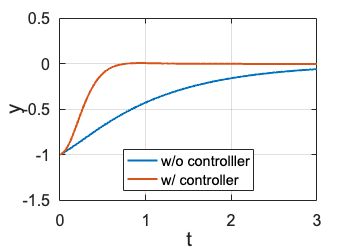

figure();
t = 0:0.01:3;

y = initial(P, [-1, 0.5], t);
plot(t, y, 'linewidth', 2, 'DisplayName', 'w/o controlller');
hold on;

y = initial(Gfb, [-1, 0.5, 0, 0], t);
plot(t, y, 'linewidth', 2, 'DisplayName', 'w/ controller');
hold on;

plot_set(gcf, 't', 'y', 'best')
ylim([-1.5, 0.5])

## 外乱オブザーバ

出力に0.5の定値外乱が加わるとする

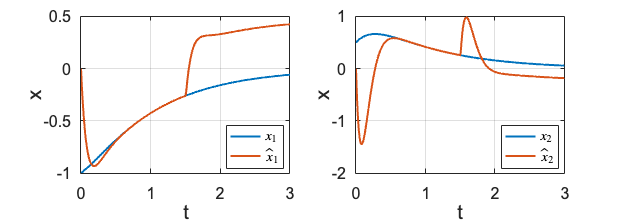

t = 0:0.01:3;
X0 = [-1, 0.5];
d = 0.5*(t>1.5);
x = initial(G, X0, t);

figure();
subplot(1,2,1);
plot(t, x(:,1), 'linewidth', 2);
hold on;
subplot(1,2,2);
plot(t, x(:,2), 'linewidth', 2);
hold on;

%%%%
% 入力 u = Fx
u = [0 0]*x';
% 出力 y = Cx + d
y = P.C*x' + d;
% オブザーバで推定した状態の振る舞い
xhat = lsim(Obs, [u ; y], t, [0, 0]);
subplot(1,2,1);
plot(t, xhat(:,1), 'linewidth', 2);
plot_set(gcf, 't', 'x', 'best')
legend('$x_1$','$\hat{x}_1$', 'Interpreter', 'latex');
subplot(1,2,2);
plot(t, xhat(:,2), 'linewidth', 2);
plot_set(gcf, 't', 'x', 'best')
legend('$x_2$','$\hat{x}_2$', 'Interpreter', 'latex');

set(gcf,'Position',[100 100 700 250])

% オブザーバ極
observer_poles=[-10+5j,-10-5j, -3] ;

% オブザーバゲインの設計（状態フィードバックの双対）
Abar = [ P.A zeros(2,1); zeros(1,3) ];
Bbar = [ P.B ; 0  ];
Cbar = [ P.C, 1   ];

Lbar = -acker(Abar', Cbar', observer_poles)'

Lbar =    75.7500
  -91.0000
  -93.7500



% Obs = ss(Abar+Bbar*Fbar+Lbar*Cbar, -Lbar, np.eye(3), [[0],[0],[0]] )
Aob = Abar + Lbar*Cbar;
Bob = [Bbar -Lbar];
Obs = ss(Aob, Bob, eye(3), zeros(3,2))

Obs =
 
  A = 
           x1      x2      x3
   x1   75.75       1   75.75
   x2     -95      -5     -91
   x3  -93.75       0  -93.75
 
  B = 
           u1      u2
   x1       0  -75.75
   x2       1      91
   x3       0   93.75
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
連続時間状態空間モデル。


pole(Obs)

ans =  -10.0000 + 5.0000i
 -10.0000 - 5.0000i
  -3.0000 + 0.0000i


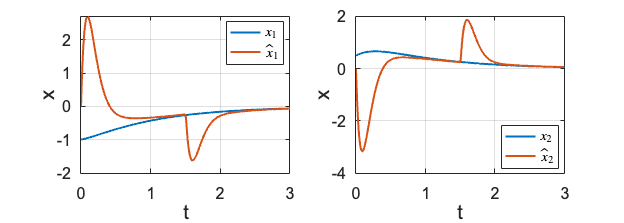

t = 0:0.01:3;
X0 = [-1, 0.5];
d = 0.5*(t>1.5);
x = initial(G, X0, t);

figure();
subplot(1,2,1);
plot(t, x(:,1), 'linewidth', 2);
hold on;
subplot(1,2,2);
plot(t, x(:,2), 'linewidth', 2);
hold on;

%%%%
% 入力 u = Fx
u = [0 0]*x';
% 出力 y = Cx + d
y = P.C*x' + d;
% オブザーバで推定した状態の振る舞い
xhat = lsim(Obs, [u ; y], t, [0, 0, 0]);
subplot(1,2,1);
plot(t, xhat(:,1), 'linewidth', 2);
plot_set(gcf, 't', 'x', 'best')
legend('$x_1$','$\hat{x}_1$', 'Interpreter', 'latex');
subplot(1,2,2);
plot(t, xhat(:,2), 'linewidth', 2);
plot_set(gcf, 't', 'x', 'best')
legend('$x_2$','$\hat{x}_2$', 'Interpreter', 'latex');

set(gcf,'Position',[100 100 700 250])

## 定常カルマンフィルタ

A = [0 1; -4 -5];
B = [0; 1];
C = [1 0 ; 0 1];
D = [0; 0];
P = ss(A, B, C, D);
C1 = [1,0];
QN = 1;
RN = 1;
L = lqe(P.A, P.B, C1, QN, RN);
L = -L

L =    -0.0246
   -0.0003


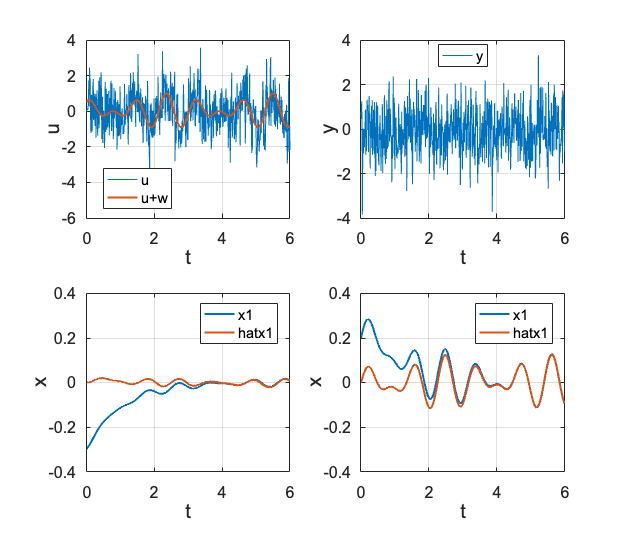


% [kalmf, L, Pk, Mk] = kalman(P,QN,RN);
% kalmf

t = 0:0.01:6;
u = 0.5*sin(6*t)+0.5*cos(8*t);
w = sqrt(QN).*randn(size(t,2),1)';
v = sqrt(RN).*randn(size(t,2),1)';

Obs = ss(P.A + L*C1, [P.B, -L], eye(2), [0,0; 0,0] );

X0 = [-0.3, 0.2];
x = lsim(P, u+w, t, X0);
xorg = lsim(P, u, t, X0);
y = x(:, 1)+v';
xhat = lsim(Obs, [u', y], t, [0, 0 ]);

figure();
subplot(2,2,1);
plot(t, u+w, 'linewidth', 0.1, 'DisplayName','u');
hold on; 
plot(t, u, 'linewidth', 2, 'DisplayName','u+w');
plot_set(gcf, 't', 'u', 'best');
subplot(2,2,2);
plot(t, y, 'linewidth', 0.1, 'DisplayName','y');
plot_set(gcf, 't', 'y', 'best')
subplot(2,2,3);
plot(t, xorg(:,1), 'linewidth', 2, 'DisplayName','x1');
hold on;
plot(t, xhat(:,1), 'linewidth', 2, 'DisplayName','hatx1');
plot_set(gcf, 't', 'x', 'best');
ylim([-0.4, 0.4]);
subplot(2,2,4);
plot(t, xorg(:,2), 'linewidth', 2, 'DisplayName','x1');
hold on;
plot(t, xhat(:,2), 'linewidth', 2, 'DisplayName','hatx1');
plot_set(gcf, 't', 'x', 'best');
ylim([-0.4, 0.4]);
set(gcf,'Position',[100 100 700 600])

## ロバスト制御

g  = 9.81;                % 重力加速度[m/s^2]
l  = 0.2;                 % アームの長さ[m]
M  = 0.5;                 % アームの質量[kg]
mu = 1.5e-2;              % 粘性摩擦係数[kg*m^2/s]
J  = 1.0e-2;              % 慣性モーメント[kg*m^2]

P = tf( [0,1], [J, mu, M*g*l] );

ref = 30; % 目標角度 [deg]

### **乗法的不確かさ**

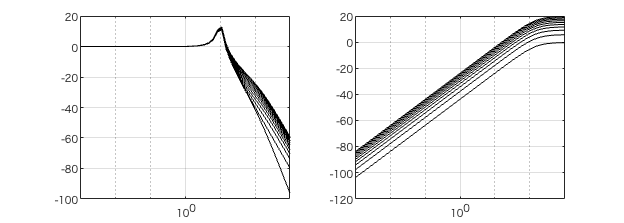

% 垂直駆動アームのノミナルモデル
Pn = tf( [0,1], [J, mu, M*g*l] );

% 不確かさ
delta = -1:0.1:1;
WT = tf( [10, 0], [1, 150]);

figure();
for i=1:1:size(delta,2)
    % 不確かさをもつ制御対象
    P = (1 + WT*delta(i))*Pn;
    [gain, ~, w] = bode(P, logspace(-3,3));
    subplot(1,2,1);
    semilogx(w, 20*log10(gain(:)), 'k', 'LineWidth', 1);
    hold on; grid on;
    
    % 乗法的不確かさ
    DT = (P - Pn)/Pn;
    [gain, ~, w] = bode(DT, logspace(-3,3));
    subplot(1,2,2);
    semilogx(w, 20*log10(gain(:)), 'k', 'LineWidth', 1);
    hold on; grid on;
end
set(gcf,'Position',[100 100 700 250])

### 混合感度問題

WS = tf( [0, 1], [1, 1, 0.25]); % 感度関数に対する重み関数 
WU = tf(1, 1);
WT = tf( [10, 0], [1, 150]); % 相補感度関数に対する重み関数

% 混合感度問題
[K, ~, gamma] = mixsyn(Pn, WS, WU, WT);

tf(K)

ans =
 
     3.54 s^4 + 539.7 s^3 + 1642 s^2 + 5.316e04 s + 4.843e04
  -------------------------------------------------------------
  s^5 + 161.3 s^4 + 1850 s^3 + 2.013e04 s^2 + 1.882e04 s + 4600
 
連続時間の伝達関数です。
モデル プロパティ


gamma

gamma = 0.9600

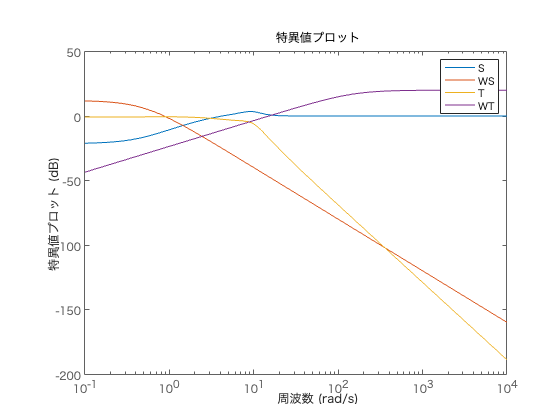


L = Pn*K;
I = eye(size(L));
S = feedback(I, L);
T = I-S;

figure();
sigma(S, WS, T, WT, {0.1,10000})
legend('S', 'WS', 'T','WT')

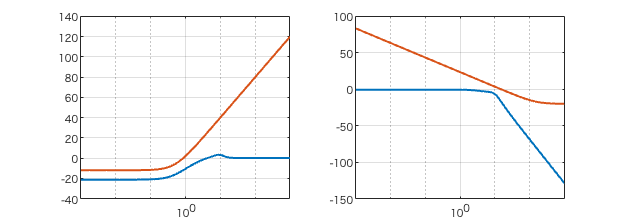

figure();
% 感度関数
Ssys = feedback(1, Pn*K);
[gain, ~, w] = bode(Ssys, logspace(-3,3));
subplot(1,2,1);
semilogx(w, 20*log10(gain(:)), 'LineWidth', 2);
hold on; grid on;

[gain, ~, w] = bode(1/WS, logspace(-3,3));
subplot(1,2,1);
semilogx(w, 20*log10(gain(:)), 'LineWidth', 2);

% 相補感度関数
Tsys = feedback(Pn*K, 1);
[gain, ~, w] = bode(Tsys, logspace(-3,3));
subplot(1,2,2);
semilogx(w, 20*log10(gain(:)), 'LineWidth', 2);
hold on; grid on;

[gain, ~, w] = bode(1/WT, logspace(-3,3));
subplot(1,2,2);
semilogx(w, 20*log10(gain(:)), 'LineWidth', 2);
set(gcf,'Position',[100 100 700 250])

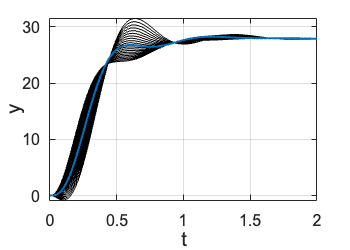

figure();
t = 0:0.01:2;
for i = 1:1:size(delta,2)
    P = (1 + WT*delta(i))*Pn;
    Gyr = feedback(P*K, 1);
   
    y = step(Gyr, t);
    plot(t,y*ref, 'k', 'linewidth', 1)
    hold on;
end

Gyr = feedback(Pn*K, 1);
y = step(Gyr, t);
plot(t,y*ref, 'linewidth', 2)

plot_set(gcf, 't', 'y')

ナイキスト軌跡

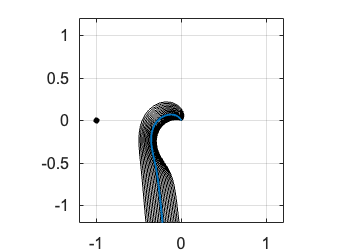

figure();

for i = 1:1:size(delta,2)
    P = (1 + WT*delta(i))*Pn;
   
    [x, y] = nyquist(P*K, logspace(-3,5,1000));
    plot(x(:), y(:), 'k', 'LineWidth', 1);
    hold on;
end
[x, y] = nyquist(Pn*K, logspace(-3,5,1000));
plot(x(:), y(:), 'LineWidth', 2);
scatter(-1, 0, 'filled', 'k');
plot_set(gcf, '', '')
xlim(gca, [-1.2, 1.2])
ylim(gca, [-1.2, 1.2])
axis square

### PID制御との比較

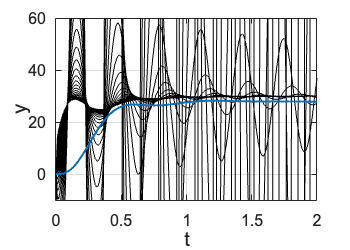

figure();
t = 0:0.01:2;
kp = 2;
kd = 0.1;
ki = 10;
Kpid = tf([kd, kp, ki], [1, 0]);

for i = 1:1:size(delta,2)
    P = (1 + WT*delta(i))*Pn;
    Gyr = feedback(P*Kpid, 1);
   
    y = step(Gyr, t);
    plot(t,y*ref, 'k', 'linewidth', 1)
    hold on;
end

Gyr = feedback(Pn*K, 1);
y = step(Gyr, t);
plot(t,y*ref, 'linewidth', 2)

plot_set(gcf, 't', 'y')
ylim([-10, 60])

ナイキスト軌跡

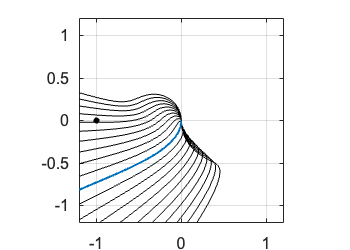

figure();

for i = 1:1:size(delta,2)
    P = (1 + WT*delta(i))*Pn;
   
    [x, y] = nyquist(P*Kpid, logspace(-3,5,1000));
    plot(x(:), y(:), 'k', 'LineWidth', 1);
    hold on;
end
[x, y] = nyquist(Pn*Kpid, logspace(-3,5,1000));
plot(x(:), y(:), 'LineWidth', 2);
scatter(-1, 0, 'filled', 'k');
plot_set(gcf, '', '')
xlim(gca, [-1.2, 1.2])
ylim(gca, [-1.2, 1.2])
axis square

## ディジタル実装

P = tf([0, 1], [0.5, 1])

P =
 
      1
  ---------
  0.5 s + 1
 
連続時間の伝達関数です。
モデル プロパティ


ts = 0.2;

Pd1 = c2d(P, ts, 'zoh')

Pd1 =
 
    0.3297
  ----------
  z - 0.6703
 
サンプル時間:  0.2 seconds
離散時間の伝達関数です。
モデル プロパティ


Pd2 = c2d(P, ts, 'tustin')

Pd2 =
 
  0.1667 z + 0.1667
  -----------------
     z - 0.6667
 
サンプル時間:  0.2 seconds
離散時間の伝達関数です。
モデル プロパティ


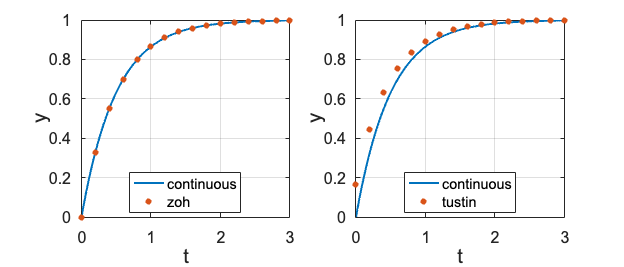

figure();

t = 0:0.01:3;
y = step(P, t);
subplot(1,2,1);
plot(t, y, 'linewidth', 2, 'DisplayName', 'continuous');
hold on; grid on;
subplot(1,2,2);
plot(t, y, 'linewidth', 2, 'DisplayName', 'continuous');
hold on; grid on;

td = 0:ts:3;
y = step(Pd1, td);
subplot(1,2,1);
scatter(td, y, 'filled', 'DisplayName','zoh');
plot_set(gcf, 't', 'y', 'best')

y = step(Pd2, td);
subplot(1,2,2);
scatter(td, y, 'filled', 'DisplayName','tustin');
plot_set(gcf, 't', 'y', 'best')

set(gcf,'Position',[100 100 700 300])

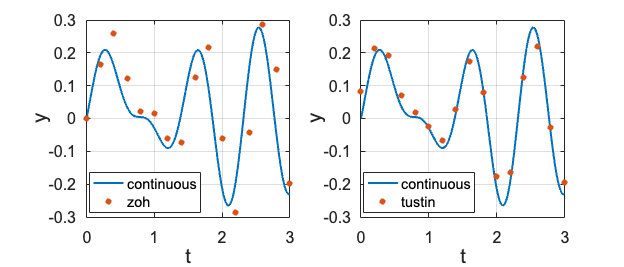

figure();

t = 0:0.01:3;
Uc = 0.5*sin(6*t) + 0.5*cos(8*t);

y = lsim(P, Uc, t);
subplot(1,2,1);
plot(t, y, 'linewidth', 2, 'DisplayName', 'continuous');
hold on; grid on;
subplot(1,2,2);
plot(t, y, 'linewidth', 2, 'DisplayName', 'continuous');
hold on; grid on;

td = 0:ts:3;
Ud = 0.5*sin(6*td) + 0.5*cos(8*td);
y = lsim(Pd1, Ud, td);
subplot(1,2,1);
scatter(td, y, 'filled', 'DisplayName','zoh');
plot_set(gcf, 't', 'y', 'best')

y = lsim(Pd2, Ud, td);
subplot(1,2,2);
scatter(td, y, 'filled', 'DisplayName','tustin');
plot_set(gcf, 't', 'y', 'best')

set(gcf,'Position',[100 100 700 300])

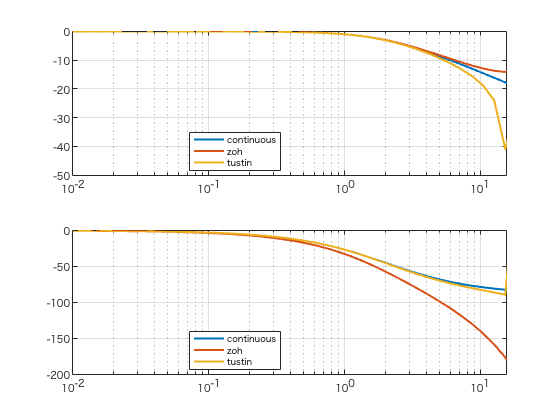

figure();

[gain, phase, w] = bode(P, logspace(-2,2));
gainLog = 20*log10(gain(:));
phaseDeg = phase(:);

subplot(2,1,1);
semilogx(w, gainLog, 'LineWidth', 2, 'DisplayName', 'continuous');
hold on;
subplot(2,1,2);
semilogx(w, phaseDeg, 'LineWidth', 2, 'DisplayName','continuous');
hold on;

[gain, phase, w] = bode(Pd1, logspace(-2,2));
gainLog = 20*log10(gain(:));
phaseDeg = phase(:);

subplot(2,1,1);
semilogx(w, gainLog, 'LineWidth', 2, 'DisplayName', 'zoh');
hold on;
subplot(2,1,2);
semilogx(w, phaseDeg, 'LineWidth', 2, 'DisplayName','zoh');
hold on;

[gain, phase, w] = bode(Pd2, logspace(-2,2));
gainLog = 20*log10(gain(:));
phaseDeg = phase(:);

subplot(2,1,1);
semilogx(w, gainLog, 'LineWidth', 2, 'DisplayName', 'tustin');
hold on; grid on; legend('Location','best');
xlim([0.01, pi/ts])
subplot(2,1,2);
semilogx(w, phaseDeg, 'LineWidth', 2, 'DisplayName','tustin');
hold on; grid on; legend('Location','best');
xlim([0.01, pi/ts])

ts = 0.5;
Pd1 = c2d(P, ts, 'zoh')

Pd1 =
 
    0.6321
  ----------
  z - 0.3679
 
サンプル時間:  0.5 seconds
離散時間の伝達関数です。
モデル プロパティ


Pd2 = c2d(P, ts, 'tustin')

Pd2 =
 
  0.3333 z + 0.3333
  -----------------
     z - 0.3333
 
サンプル時間:  0.5 seconds
離散時間の伝達関数です。
モデル プロパティ


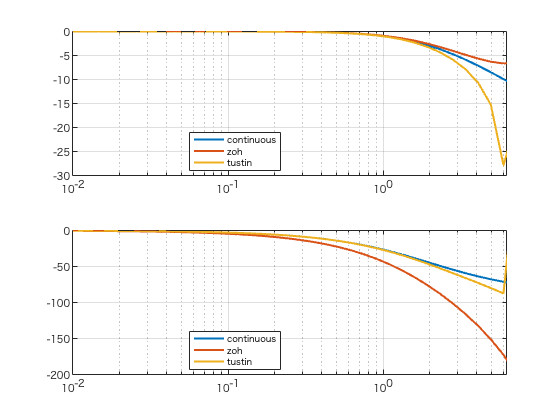


figure();

[gain, phase, w] = bode(P, logspace(-2,2));
gainLog = 20*log10(gain(:));
phaseDeg = phase(:);

subplot(2,1,1);
semilogx(w, gainLog, 'LineWidth', 2, 'DisplayName', 'continuous');
hold on;
subplot(2,1,2);
semilogx(w, phaseDeg, 'LineWidth', 2, 'DisplayName','continuous');
hold on;

[gain, phase, w] = bode(Pd1, logspace(-2,2));
gainLog = 20*log10(gain(:));
phaseDeg = phase(:);

subplot(2,1,1);
semilogx(w, gainLog, 'LineWidth', 2, 'DisplayName', 'zoh');
hold on;
subplot(2,1,2);
semilogx(w, phaseDeg, 'LineWidth', 2, 'DisplayName','zoh');
hold on;

[gain, phase, w] = bode(Pd2, logspace(-2,2));
gainLog = 20*log10(gain(:));
phaseDeg = phase(:);

subplot(2,1,1);
semilogx(w, gainLog, 'LineWidth', 2, 'DisplayName', 'tustin');
hold on; grid on; legend('Location','best');
xlim([0.01, pi/ts])
subplot(2,1,2);
semilogx(w, phaseDeg, 'LineWidth', 2, 'DisplayName','tustin');
hold on; grid on; legend('Location','best');
xlim([0.01, pi/ts])

## 最適制御（未実装）